clear all
close all
f=@(x,y) x+y-3;
g=@(x,y) x.^2+y.^2-9;
fimplicit(f,[-10 10])
hold on
fimplicit(g,[-10 10])

F=@(x) [f(x(1),x(2));g(x(1),x(2))];
J=@(x) [1 1; 2*x(1) 2*x(2)];
[zero,fz,iter]=newtonMat(F,J,[1;5],1e-8,20)

zero =    -0.0000
    3.0000


fz = 	1.0e+-10 *

         0
    0.1098


iter = 5

plot(zero(1),zero(2),"or")
[zm,fzm]=fsolve(F,[1;5])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


zm =    -0.0000
    3.0000


fzm = 	1.0e+-7 *

    0.0000
    0.2820


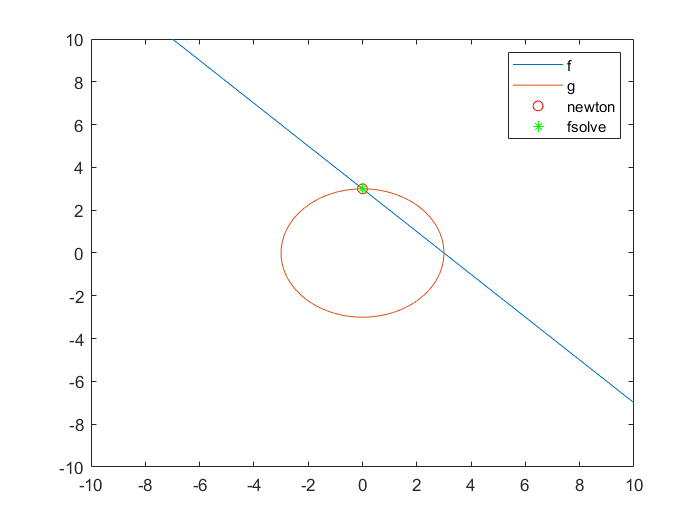

plot(zm(1),zm(2),"*g")
legend("f","g","newton","fsolve")

clear all
close all
f=@(x,y) x.^2+y.^2-2;
g=@(x,y) exp(x-1)+y.^3-2;
fimplicit(f,[-10 10])
hold on
fimplicit(g,[-10 10])

F=@(x) [f(x(1),x(2));g(x(1),x(2))];
J=@(x) [2*x(1) 2*x(2); exp(x(1)-1) 3*x(2)^2];
[zero,fz,iter]=newtonMat(F,J,[0;0],1e-8,20)

zero =    Inf
  -Inf


fz =    Inf
   NaN


iter = 1

plot(zero(1),zero(2),"or")
[zm,fzm]=fsolve(F,[0;0])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


zm =     1.0000
    1.0000


fzm = 	1.0e+-12 *

    0.3153
    0.7638


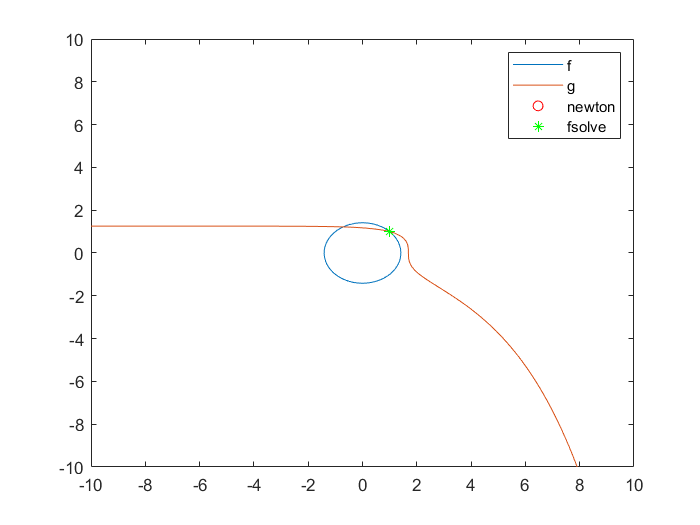

plot(zm(1),zm(2),"*g")
legend("f","g","newton","fsolve")

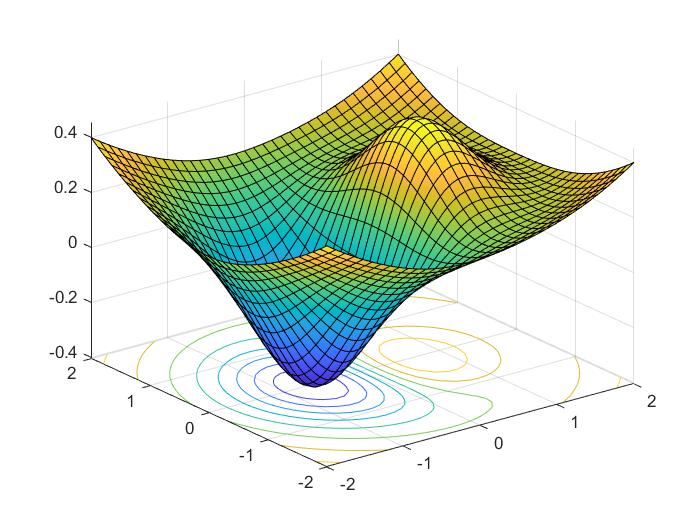

clear all
close all
f=@(x,y) x.*exp(-(x.^2+y.^2))+(x.^2+y.^2)/20;
fsurf(f,[-2 2],'ShowContours','on')

fcontour(f,[-2 2])
opt=optimoptions('fminunc','Display','iter');
fun=@(x) f(x(1),x(2));
z=fminunc(fun,[-0.5;0],opt)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          -0.3769                         0.339
     1           6        -0.379694              1          0.286  
     2           9        -0.405023              1         0.0284  
     3          12        -0.405233              1        0.00386  
     4          15        -0.405237              1       3.17e-05  
     5          18        -0.405237              1       3.35e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

z =    -0.6691
    0.0000


hold on
plot(z(1),z(2),'sr')
opt=optimset('Display','iter');
z1=fminsearch(fun,[-0.5;0],opt)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -0.3769         
     1            3        -0.384745         initial simplex
     2            4        -0.384745         reflect
     3            6        -0.396592         expand
     4            8        -0.400606         expand
     5           10        -0.404889         reflect
     6           12        -0.405204         reflect
     7           14        -0.405204         contract outside
     8           16        -0.405204         contract inside
     9           18        -0.405205         contract inside
    10           20        -0.405218         contract outside
    11           22        -0.405237         contract inside
    12           23        -0.405237         reflect
    13           25        -0.405237         contract inside
    14           27        -0.405237         contract inside
    15           29        -0.405237         contract inside
    16           31        -0.

z1 =    -0.6690
   -0.0001


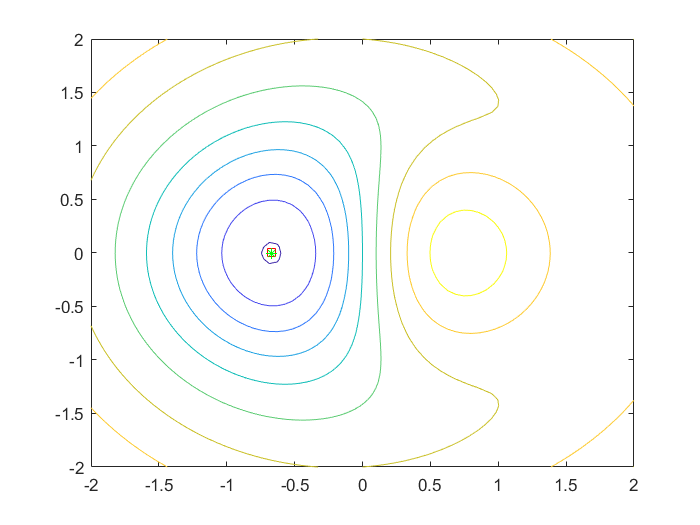

plot(z1(1),z1(2),'*g')

z-z1

ans = 	1.0e+-3 *

   -0.0464
    0.1446


fun(z)-fun(z1)

ans = -1.2028e-08

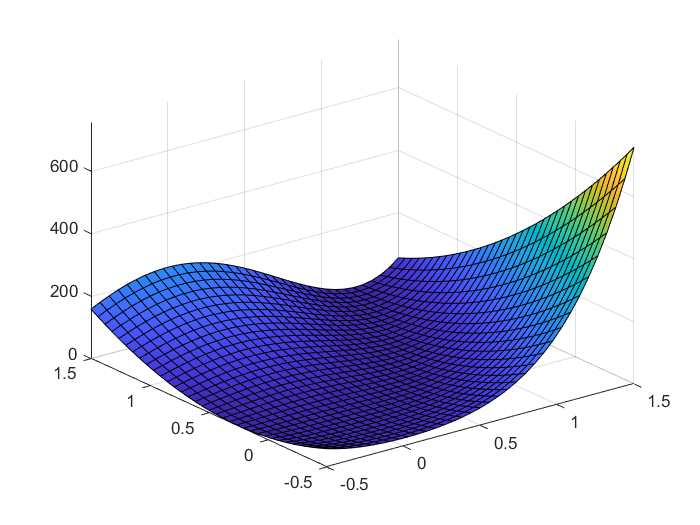

clear all
close all
f=@(x,y) 100*(y-x^2)^2+(1-x)^2;
fsurf(f,[-0.5 1.5])

fcontour(f,[-0.5 1.5],'LevelList',[1:5:100])

F=@(x) f(x(1),x(2));
[x1,fz1,flag1,output1]=fminunc(F,[0;0])


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x1 =     1.0000
    1.0000


fz1 = 1.9474e-11

flag1 = 1

output1 = struct with fields:
       iterations: 20
        funcCount: 81
         stepsize: 8.0512e-06
     lssteplength: 1
    firstorderopt: 1.0576e-06
        algorithm: 'quasi-newton'
          message: '↵Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 3.525237e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.↵↵'


hold on
plot(x1(1),x1(2),'or')
[x2,fz2,flag2,output2]=fminsearch(F,[0;0])

x2 =     1.0000
    1.0000


fz2 = 3.6862e-10

flag2 = 1

output2 = struct with fields:
    iterations: 79
     funcCount: 146
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


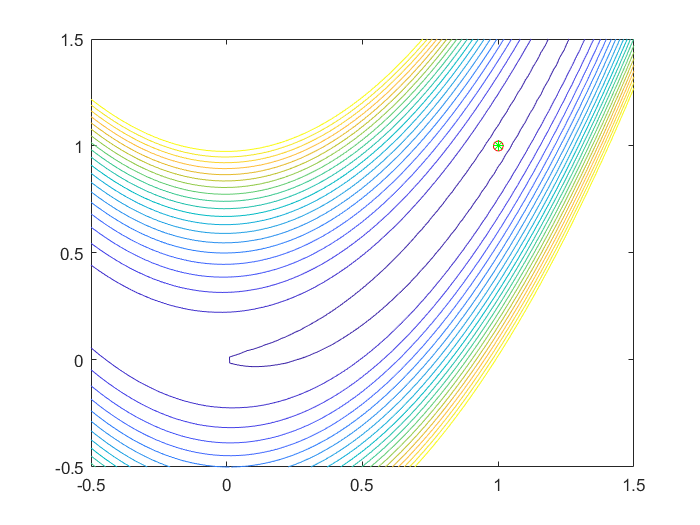

plot(x2(1),x2(2),'*g')

options=optimoptions('fminunc','Algorithm','trust-region','SpecifyObjectiveGradient',true);
options.Display='iter';
[x,fval,exitf,output,grad]= fminunc(@funcongrad,[-1.2,1],options)


                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0               24.2                           216                
     1            4.73188       0.381476           4.64           1
     2            4.73188        4.95098           4.64           1
     3            4.73188        1.23775           4.64           0
     4            4.21434       0.309436            7.5           0
     5            3.63508       0.618873           24.9           1
     6            2.77342       0.171903           7.21           1
     7            2.77342       0.681819           7.21           1
     8            2.42268       0.154718           4.22           0
     9            1.96107       0.309436           8.11           1
    10            1.47419       0.164139           4.56           1
    11            1.16812       0.222598            9.2           1
    12           0.786727       0.108265        

x =     1.0000    1.0000


fval = 4.0035e-13

exitf = 3

output = struct with fields:
         iterations: 27
          funcCount: 28
           stepsize: 4.7844e-04
       cgiterations: 22
      firstorderopt: 1.6672e-05
          algorithm: 'trust-region'
            message: '↵Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.↵↵'
    constrviolation: []


grad = 	1.0e+-4 *

    0.1667
   -0.0879


clear all
close all
f=@(x,y) 100*(y-x^2)^2+(1-x)^2;
F=@(x) f(x(1),x(2));
fcontour(f,[-0.5 1.5],'LevelList',[1:5:100])

g=@(x,y) x+2*y-1;
hold on
fimplicit(g,[-0.5 1.5],'r')
plot(1,1,'og')
A=[1 2];b=1;
x=fmincon(F,[-1;2],A,b);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


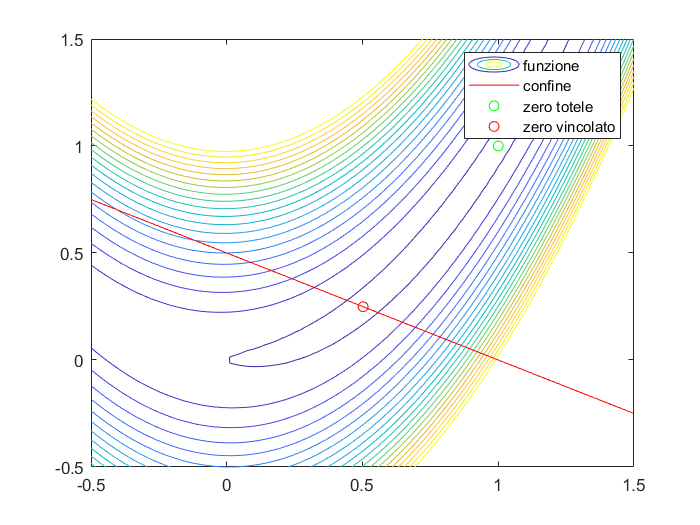

plot(x(1),x(2),'or')
legend('funzione','confine','zero totele','zero vincolato')
hold off

fcontour(f,[-0.5 1.5],'LevelList',[1:5:100])

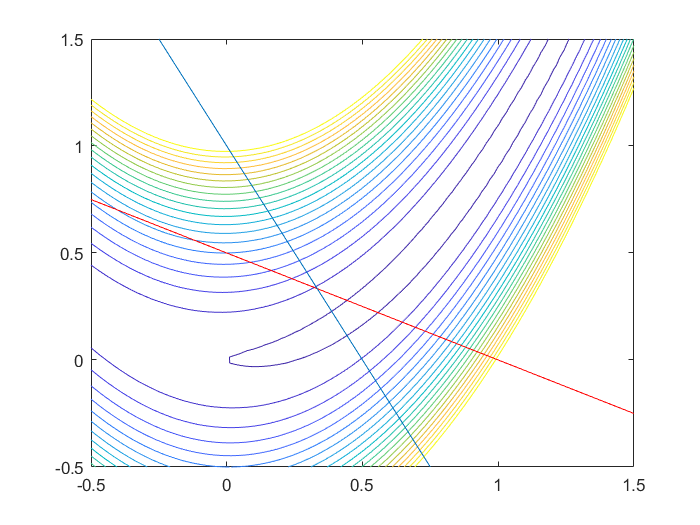

hold on
fimplicit(g,[-0.5 1.5],'r')
ge=@(x,y) 2*x+y-1;
fimplicit(ge,[-0.5 1.5])

Ae=[2;1];be=1;
x=fmincon(F,[-1;2],A,b,Ae,be);

Error using fmincon (line 311)
Aeq must have 2 column(s).

plot(x(1),x(2),'or')
legend('funzione','confine','zero vincolato')